# Battery Discharge Revisited

Data from lesson

tt = [0 1 2 3 4 5 6 7 8 9]; % hrs
vv = [13.5521	8.5037	6.8038	4.3123	3.3543	3.8569	2.9397	1.1442	1.7904	0.6489]; % V
figure;
clf;
plot(tt, vv, 'ko', 'DisplayName','Data')
xlabel("Time (hrs)")
ylabel("Battery Voltage (V)")
grid('on')
title ("Battery Discharge")

Implement the following model of voltage discharge:

function v = batt_model(params, t)
    Vo = params(1);
    k = params(2);
    b = params(3);
    c = params(4);

    v = Vo*(t-b).*(1-exp(-k*t))+c;
end

Use `nlfit`  to perform the nonlinear regression.

For the modified battery model using nlfit, the new model

does not have the same interpretation as the simpler exponential model from class.  If you start with the same initial values for the parameters:

Vo = 13.5; % V

k = 1/4; % 1/hr

c = 0.5; % V

b = 0;

The resulting function is a very poor approximation of the data.  Furthermore, when you run the nlfit algorithm you will likely get a warning such as...

and the algorithm will give up, quitting early.

I recommend a small change to the initial parameters supplied to the nlfit algorithm:

Vo = 13.5; % V

k = 0.5; % 1/hr

c = 0.5; % V

b = 0;

This should allow the algorithm to converge and you should see very different numerical values for the "optimal" parameter values and a MSE figure of merit similar to that of the simpler exponential model.

Vo = 13.5;  % V
k = 0.5;    % V
b = 0;
c = 0;
params0 = [Vo, k, b, c];
[beta,R,J,CovB,MSE,ErrorModelInfo] = ...
    nlinfit(tt, vv, @batt_model, params0);

Visualize the results to verify that the model fits the data.

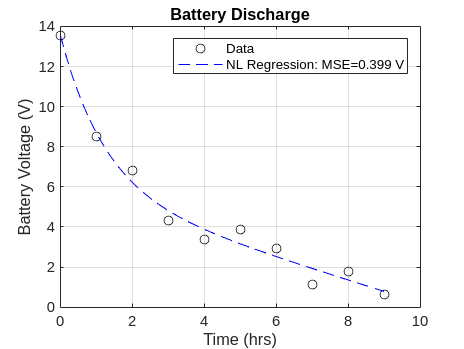

tt_reg = linspace(min(tt), max(tt), 100);
vv_reg = batt_model(beta, tt_reg);
hold on
plot(tt_reg, vv_reg, 'b--', 'DisplayName',...
    sprintf('NL Regression: MSE=%.3f V',MSE))
legend()

Compre to the results from class: `MSE = 0.549 [V]`

MSE0 = 0.549

MSE0 = 0.5490

fprintf("Reduction in MSE: %.1f %%\n", (MSE0 - MSE)/MSE0 * 100);

Reduction in MSE: 27.3 %


This is beyond what the assignment asked for, but I'm curious to 'see' the difference between the two results.

The saved workspace from the class example

bf = load('batt_fit');

Plot

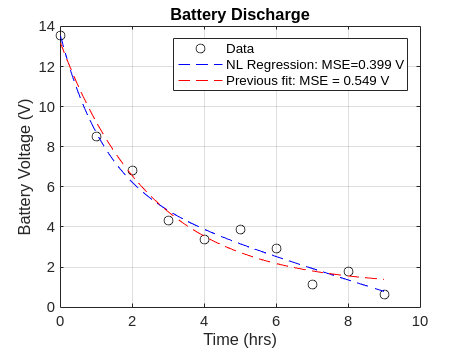

plot(bf.tt_reg, bf.vv_reg, 'r--',"displayname", ...
    sprintf("Previous fit: MSE = %.3f V", bf.MSE))